This is a simple model of walking down a ramp of incline angle $\gamma$ (Garcia et al. 1998):


$$\theta'' - \sin(\theta-\gamma) = 0$$



$$\phi'' - \sin(\theta-\gamma) +\sin(\phi) \left[\cos(\theta-\gamma) - (\theta')^2\right] = 0
$$


We can solve the problem as written. 

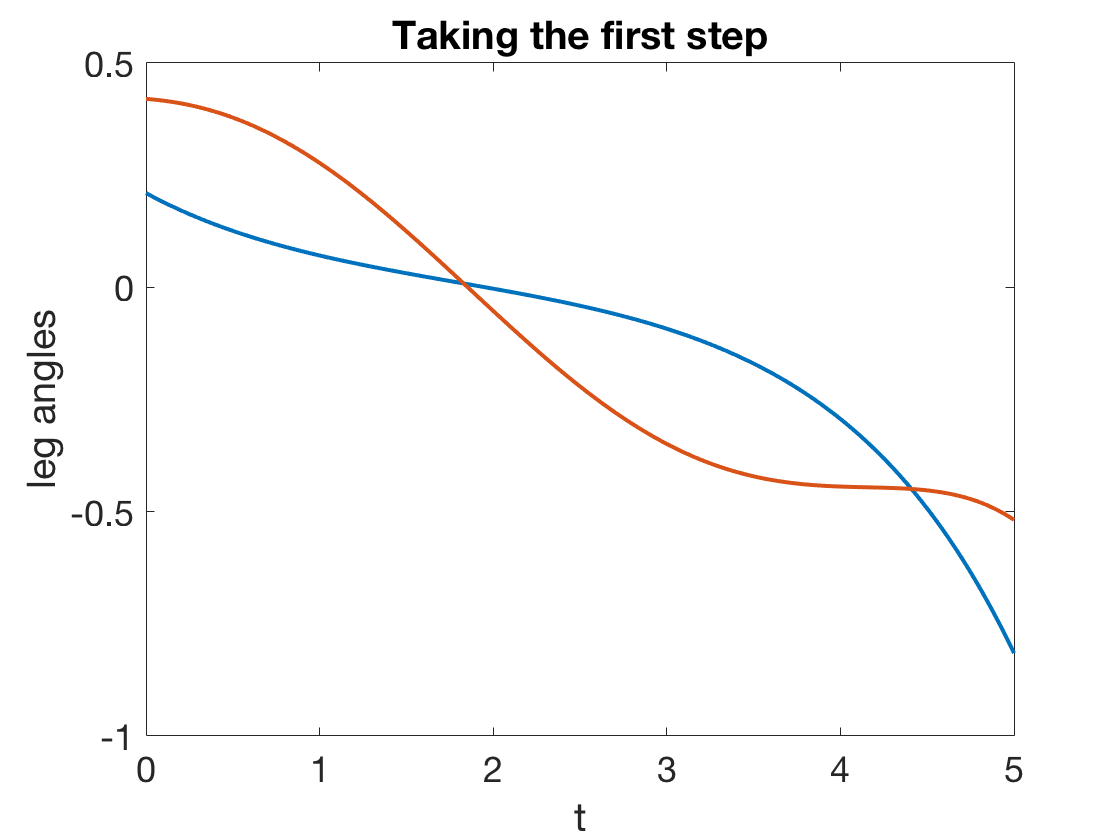

gamma = 0.011;
W = chebop([0,5]);
W.op = @(t,theta,phi) [
    diff(theta,2)-sin(theta-gamma); ...
    diff(phi,2)-sin(theta-gamma)-diff(theta).^2.*sin(phi)+cos(theta-gamma).*sin(phi)];
W.lbc = @(theta,phi) [
    theta - 0.21;
    phi - 0.42;
    diff(theta) + 0.21;
    diff(phi) + 0.03 ];

[theta,phi] = W\0;

plot([theta,phi])
xlabel('t'), ylabel('leg angles')

title('Taking the first step')

## Heel strike

The heel of the swinging leg strikes the ground when $\phi=2\theta$ (at a nonzero value). We say this happens at $t=\tau$, and the step is effectively over then. 

clf, plot([phi,2*theta])
t = find(phi==2*theta);  tau = t(end)

tau = 3.7243

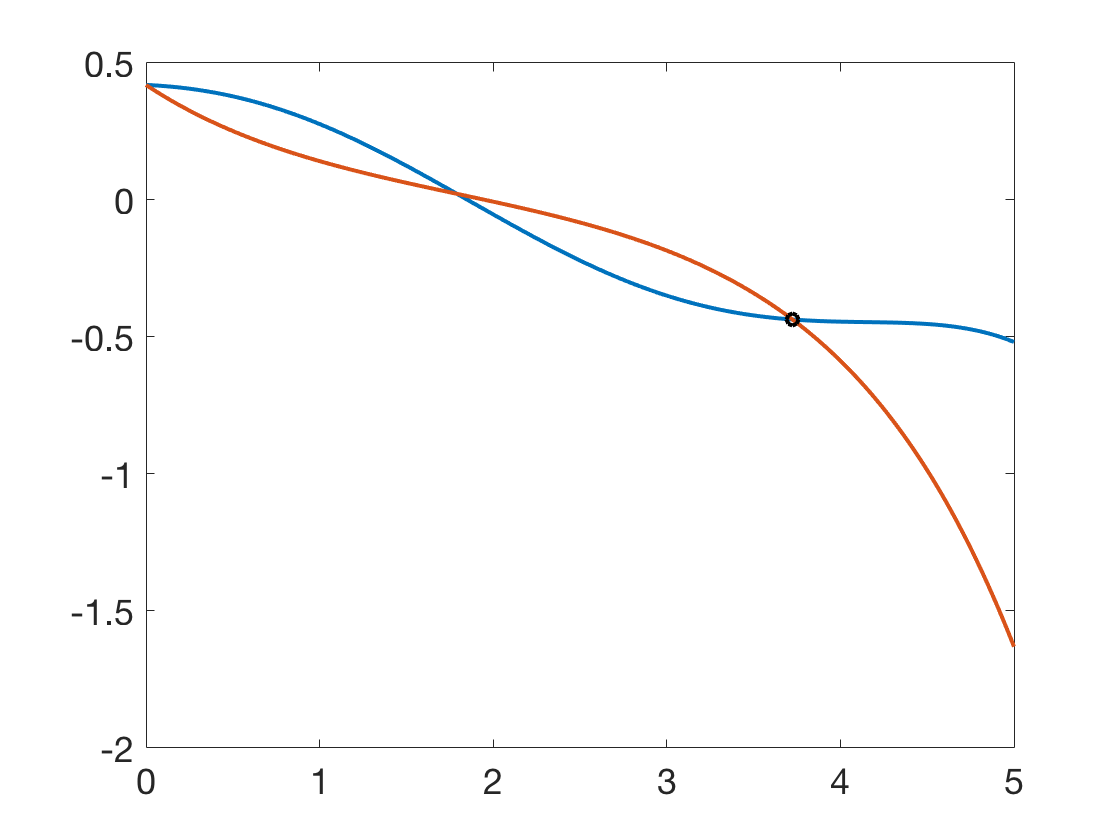

hold on, plot(tau,phi(tau),'ko')

## Step two

For the next step, new initial conditions are set by the old final conditions:


$$\left[ \matrix{\theta(\tau^+) \cr \phi(\tau^+) \cr \theta'(\tau^+) \cr \phi'(\tau^+) } \right]
  = 
  \left[\matrix{
    -1 & 0 & 0 & 0 \cr
    -2 & 0 & 0 & 0 \cr
    0 & 0 & c& 0 \cr
    0 & 0 & c(1-c) & 0 }\right]
\left[ \matrix{
    \theta(\tau^-) \cr \phi(\tau^-) \cr \theta'(\tau^-) \cr \phi'(\tau^-) }\right], \qquad c = \cos(2 \theta(\tau^-))
$$


c = cos(2*theta(tau));
A = [-1 0 0 0;
    -2 0 0 0;
    0 0 c 0;
    0 0 c*(1-c) 0];
IC = A*[theta(tau);phi(tau);deriv(theta,tau);deriv(phi,tau)]

IC =     0.2181
    0.4362
   -0.2162
   -0.0202


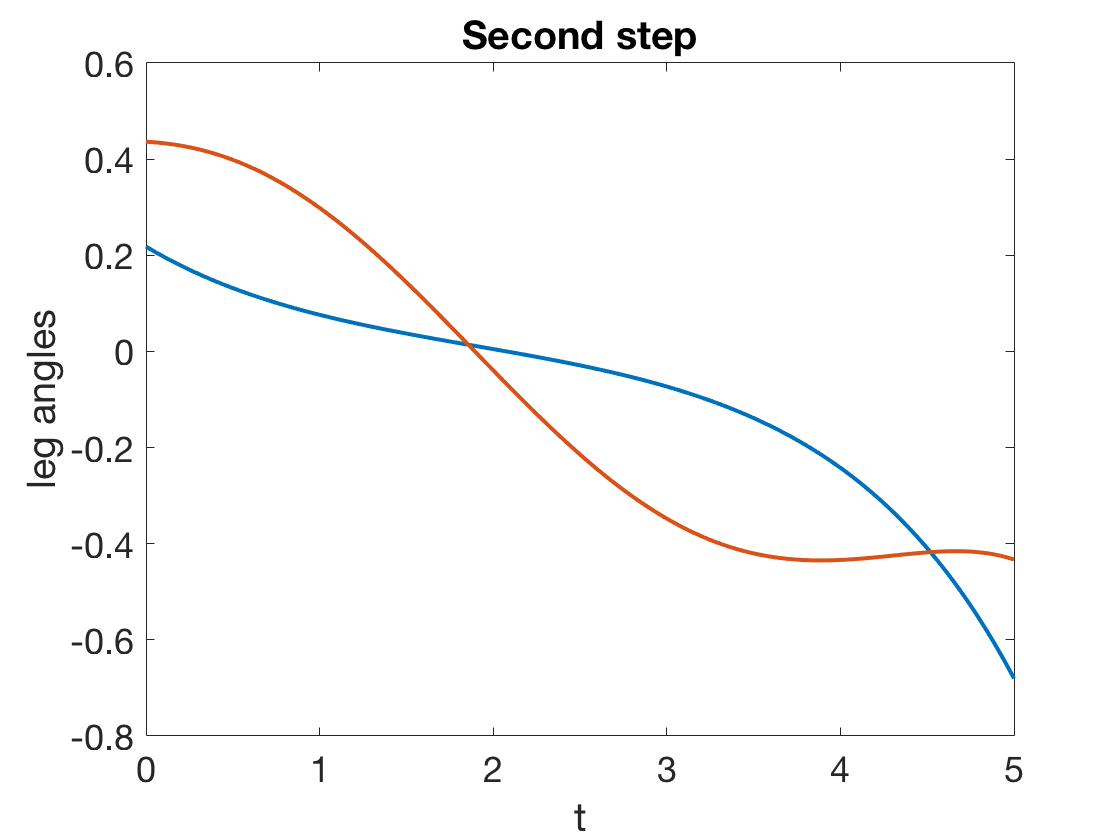

W.lbc = @(theta,phi) [theta-IC(1);phi-IC(2); ...
    diff(theta)-IC(3);diff(phi)-IC(4)];
[theta,phi] = W\0;

clf, plot([theta,phi])
xlabel('t'), ylabel('leg angles'), title('Second step')

t = find(phi==2*theta);  tau = t(end)

tau = 3.9004

## Periodic attractor

If we repeat the process, we find that the walker is attracted to a periodic solution. 

Theta = chebfun([]); Phi = chebfun([]); 
for k = 1:12
    c = cos(2*theta(tau));
    A = [-1 0 0 0; -2 0 0 0; 0 0 c 0; 0 0 c*(1-c) 0];
    IC = A*[theta(tau);phi(tau);deriv(theta,tau);deriv(phi,tau)];
    W.lbc = @(theta,phi) [theta-IC(1);phi-IC(2); ...
        diff(theta)-IC(3);diff(phi)-IC(4)];
    [theta,phi] = W\0;
    t = find(phi==2*theta);  tau = t(end)
    Theta = join(Theta,theta{0,tau});  Phi = join(Phi,phi{0,tau});
end

tau = 3.9719

tau = 3.8159

tau = 3.9013

tau = 3.9149

tau = 3.8733

tau = 3.8978

tau = 3.8959

tau = 3.8891

tau = 3.8944

tau = 3.8930

tau = 3.8922

tau = 3.8932

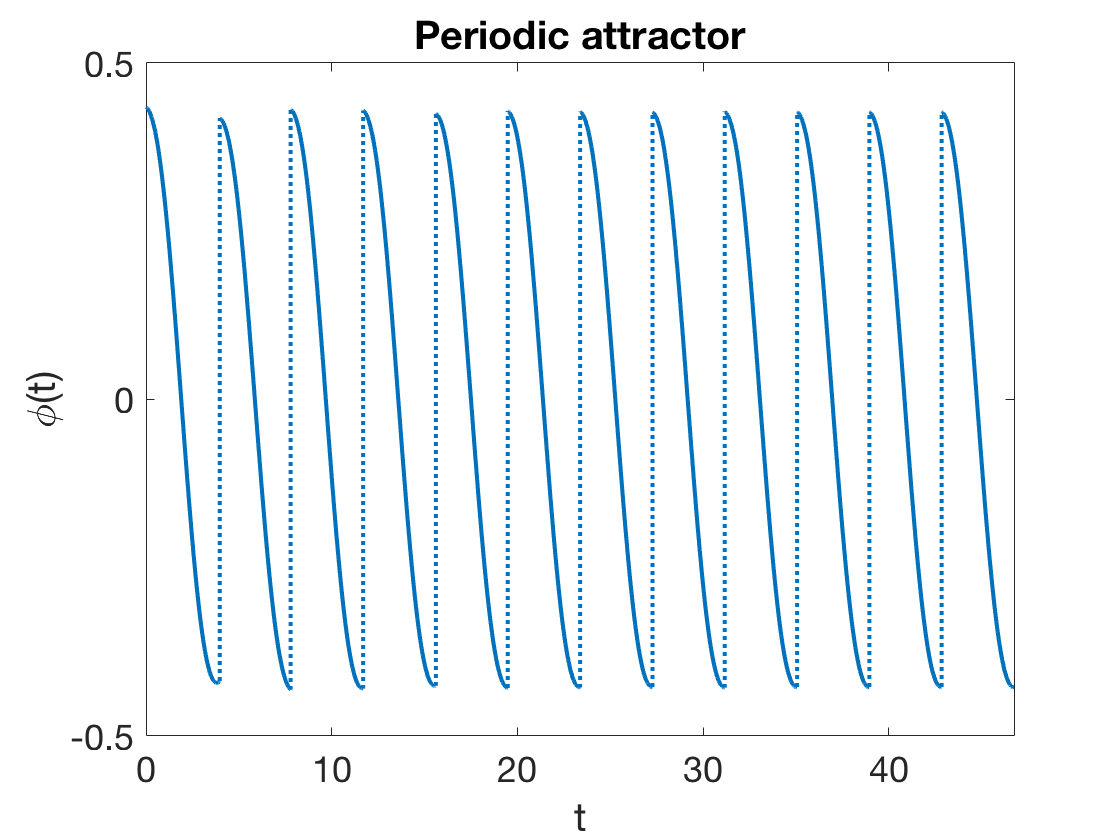


clf, plot(Phi)
xlabel('t'), ylabel('\phi(t)'), title('Periodic attractor')

## "Limping" walker

As the ramp incline increases, however, there is a period doubling bifurcation, and we are attracted to what's known as a "limping" solution. 

gamma = 0.017;
IC = [ 0.2465; 0.4931; -0.23972; -0.02856 ];
W.op = @(t,theta,phi) [
    diff(theta,2)-sin(theta-gamma); ...
    diff(phi,2)-sin(theta-gamma)-diff(theta).^2.*sin(phi)+cos(theta-gamma).*sin(phi)];

Theta = chebfun([]); Phi = chebfun([]); 
for k = 1:16
    W.lbc = @(theta,phi) [theta-IC(1);phi-IC(2); ...
        diff(theta)-IC(3);diff(phi)-IC(4)];
    [theta,phi] = W\0;
    t = find(phi==2*theta);  tau = t(end)
    Theta = join(Theta,theta{0,tau});  Phi = join(Phi,phi{0,tau});
    
    c = cos(2*theta(tau));
    A = [-1 0 0 0; -2 0 0 0; 0 0 c 0;  0 0 c*(1-c) 0];
    IC = A*[theta(tau);phi(tau);deriv(theta,tau);deriv(phi,tau)];
end

tau = 3.9179

tau = 3.9293

tau = 3.9085

tau = 3.9377

tau = 3.8972

tau = 3.9517

tau = 3.8761

tau = 3.9756

tau = 3.8377

tau = 4.0105

tau = 3.7779

tau = 4.0403

tau = 3.7307

tau = 4.0406

tau = 3.7476

tau = 4.0404

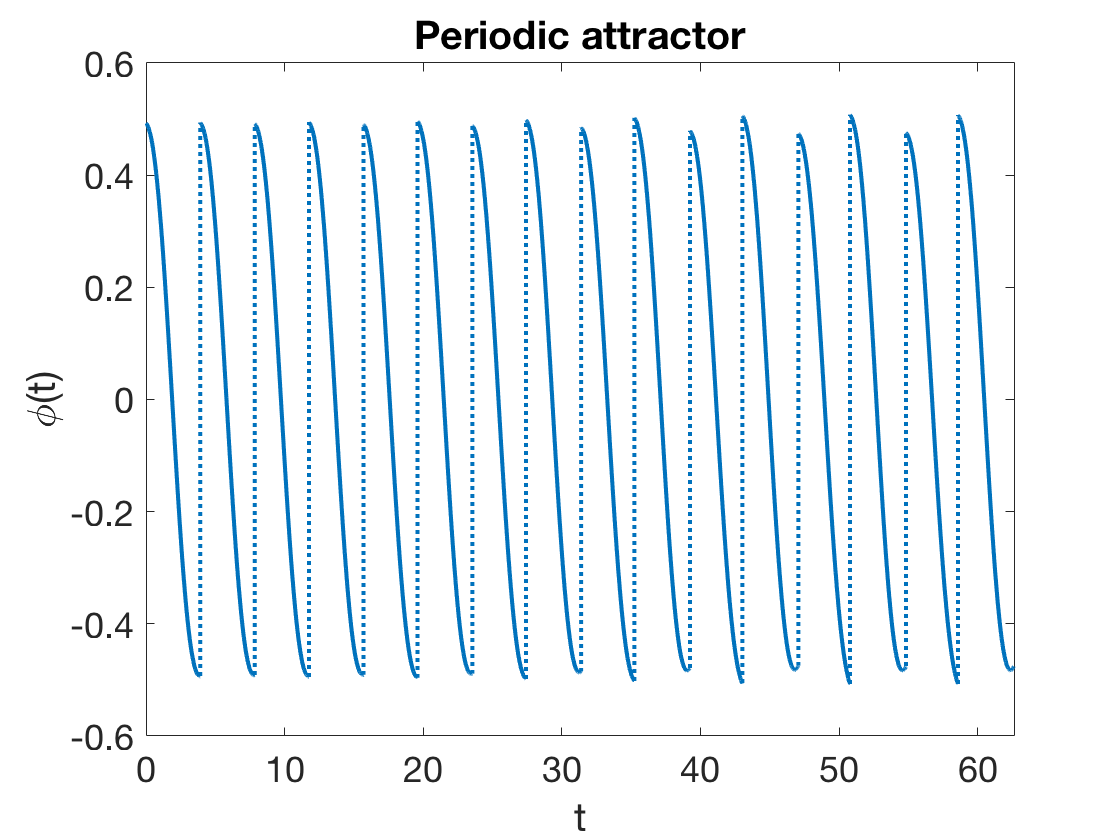


clf, plot(Phi)
xlabel('t'), ylabel('\phi(t)'), title('Periodic attractor')